tau = 0.05

tau = 0.0500

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



alpha = (s*tau + 1)^2

alpha =
 
  0.0025 s^2 + 0.1 s + 1
 
Continuous-time transfer function.




beta = (0.5*s + 1)^4

beta =
 
  0.0625 s^4 + 0.5 s^3 + 1.5 s^2 + 2 s + 1
 
Continuous-time transfer function.




GHsym = [s/alpha, -1/alpha, -1/alpha, 0;
         s/alpha, (alpha - 1/alpha)/s^2, -1/(s^2 * alpha), 1/s^2;
         (1-s/alpha)/beta, -(alpha-1/alpha)/(beta * s^2), 1/(beta*s^2*alpha), -1/(beta*s^2);
         s/(beta*alpha), (1-1/alpha)/beta, -1/(beta*alpha), 0]

GHsym =
 
  From input 1 to output...
                 s
   1:  ----------------------
       0.0025 s^2 + 0.1 s + 1
 
                 s
   2:  ----------------------
       0.0025 s^2 + 0.1 s + 1
 
                                 0.0025 s^2 - 0.9 s + 1
   3:  ---------------------------------------------------------------------------
       0.0001563 s^6 + 0.0075 s^5 + 0.1163 s^4 + 0.655 s^3 + 1.703 s^2 + 2.1 s + 1
 
                                            s
   4:  ---------------------------------------------------------------------------
       0.0001563 s^6 + 0.0075 s^5 + 0.1163 s^4 + 0.655 s^3 + 1.703 s^2 + 2.1 s + 1
 
  From input 2 to output...
                 -1
   1:  ----------------------
       0.0025 s^2 + 0.1 s + 1
 
       6.25e-06 s^4 + 0.0005 s^3 + 0.015 s^2 + 0.2 s
   2:  ---------------------------------------------
                0.0025 s^4 + 0.1 s^3 + s^2
 
                       -6.25e-06 s^4 - 0.0005 s^3 - 0.015 s^2 - 0.2 s
   3:  ------------------------



Gss = ss(GHsym, 'minimal')

Gss =
 
  A = 
              x1        x2        x3        x4        x5        x6        x7        x8        x9       x10       x11       x12       x13       x14
   x1     -15.08     3.471    -4.392    -29.03    -10.86     8.297     2.969     10.08     4.336    0.8348    -5.974    0.7976     1.302     5.588
   x2      2.936      -3.7     2.207     11.71     2.445     2.789     1.321     2.478    -2.484      1.47   -0.3066    0.3783    0.2141   -0.6533
   x3     -0.992    -0.791    -0.734    -3.744    -1.797     1.215    0.3852   -0.5845   -0.7963     2.048   -0.4637    0.3511  0.005763    0.8859
   x4     -1.183    0.1889    -2.202    -18.37     -9.85     2.939     1.727    -1.856    -7.727     6.795    -4.812    -2.306     1.533     1.274
   x5      4.279    -0.683    0.3651      2.31   -0.6163   -0.4298    0.3125    -1.295    -3.751     4.439    0.3696    -1.243   -0.5951    -2.595
   x6      3.211   -0.5126     0.274     4.822     2.242    -3.841    -1.473    -6.405   -0.9421    -1.

% SS


E1 = [1, 0, 0, 0, 0, 0;
     0, 1, 0, 0, 0, 0;
     0, 0, 1, 0, 0, -tau^2;
     0, 0, 0, 1, -tau^2, 0;
     0, 0, 0, -1/tau^2, 1, 0;
     0, 0, -1/tau^2, 0, 0, 1]

E1 =     1.0000         0         0         0         0         0
         0    1.0000         0         0         0         0
         0         0    1.0000         0         0   -0.0025
         0         0         0    1.0000   -0.0025         0
         0         0         0 -400.0000    1.0000         0
         0         0 -400.0000         0         0    1.0000



A1 = [0, 0, 0, 1, 0, 0;
      0, 0, 0, 0, 0, 1;
      0, 1, 0, 0, 0, 2*tau;
      0, 1, 0, 0, 2*tau, 0;
      0, -1/tau^2, 0, 0, -2/tau, 0;
      0, -1/tau^2, 0, 0, 0, -2/tau]

A1 =          0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000
         0    1.0000         0         0         0    0.1000
         0    1.0000         0         0    0.1000         0
         0 -400.0000         0         0  -40.0000         0
         0 -400.0000         0         0         0  -40.0000



B1 = [0, 0, 0, 0;
      0, 0 ,0 ,0;
      0, 1, 1, 0;
      0, 1, 0, 1;
      0, -1/tau^2, 0, -1/tau^2;
      0, -1/tau^2, -1/tau^2, 0]

B1 =          0         0         0         0
         0         0         0         0
         0    1.0000    1.0000         0
         0    1.0000         0    1.0000
         0 -400.0000         0 -400.0000
         0 -400.0000 -400.0000         0



L = [0, 1, 0, 0;
     0, 0, 1, 0;
     0, 0, 0, 1;
     -16, -32, -24, -8]

L =      0     1     0     0
     0     0     1     0
     0     0     0     1
   -16   -32   -24    -8



A2 = [L, zeros(4);
      zeros(4), L]

A2 =      0     1     0     0     0     0     0     0
     0     0     1     0     0     0     0     0
     0     0     0     1     0     0     0     0
   -16   -32   -24    -8     0     0     0     0
     0     0     0     0     0     1     0     0
     0     0     0     0     0     0     1     0
     0     0     0     0     0     0     0     1
     0     0     0     0   -16   -32   -24    -8



zr4 = zeros(1,4);
B2 = [zr4; zr4; zr4;
      16, 0, 0, 0;
      zr4; zr4; zr4;
      0, 16, 0, 0]

B2 =      0     0     0     0
     0     0     0     0
     0     0     0     0
    16     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0    16     0     0



zr6 = zeros(1,6);

W = [zr6; zr6; zr6;
    -16, 0, zr4;
    zr6; zr6; zr6;
    0, 16, zr4]

W =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
   -16     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0    16     0     0     0     0



Ap = [A1, zeros(6, 8);
     W, A2]

Ap =          0         0         0    1.0000         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0    0.1000         0         0         0         0         0         0         0         0
         0    1.0000         0         0    0.1000         0         0         0         0         0         0         0         0         0
         0 -400.0000         0         0  -40.0000         0         0         0         0         0         0         0         0         0
         0 -400.0000         0         0         0  -40.0000         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0    1.0000         0         0         0         0         0         0
        


Bp = [B1;
     B2]

Bp =          0         0         0         0
         0         0         0         0
         0    1.0000    1.0000         0
         0    1.0000         0    1.0000
         0 -400.0000         0 -400.0000
         0 -400.0000 -400.0000         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
   16.0000         0         0         0



E = [E1, zeros(6,8);
    zeros(8,6), eye(8)]

E =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
         0         0    1.0000         0         0   -0.0025         0         0         0         0         0         0         0         0
         0         0         0    1.0000   -0.0025         0         0         0         0         0         0         0         0         0
         0         0         0 -400.0000    1.0000         0         0         0         0         0         0         0         0         0
         0         0 -400.0000         0         0    1.0000         0         0         0         0         0         0         0         0
         0         0         0         0         0         0    1.0000         0         0         0         0         0         0         0
         


% this is zero which doesnt seem good
det(E)

ans = 0


% continue on to get C and D
C = [0, 1, zr6, zr6;
     1, 0, zr6, zr6;
     zr6, 1, 0, zr6;
     zr6, zr4, 1, 0, 0, 0]

C =      0     1     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     1     0     0     0


D = 0

D = 0

GH = dss(Ap, Bp, C, D, E)

GH =
 
  A = 
          x1    x2    x3    x4    x5    x6    x7    x8    x9   x10   x11   x12   x13   x14
   x1      0     0     0     1     0     0     0     0     0     0     0     0     0     0
   x2      0     0     0     0     0     1     0     0     0     0     0     0     0     0
   x3      0     1     0     0     0   0.1     0     0     0     0     0     0     0     0
   x4      0     1     0     0   0.1     0     0     0     0     0     0     0     0     0
   x5      0  -400     0     0   -40     0     0     0     0     0     0     0     0     0
   x6      0  -400     0     0     0   -40     0     0     0     0     0     0     0     0
   x7      0     0     0     0     0     0     0     1     0     0     0     0     0     0
   x8      0     0     0     0     0     0     0     0     1     0     0     0     0     0
   x9      0     0     0     0     0     0     0     0     0     1     0     0     0     0
   x10   -16     0     0     0     0     0   -16   -32   -24    -8     0    

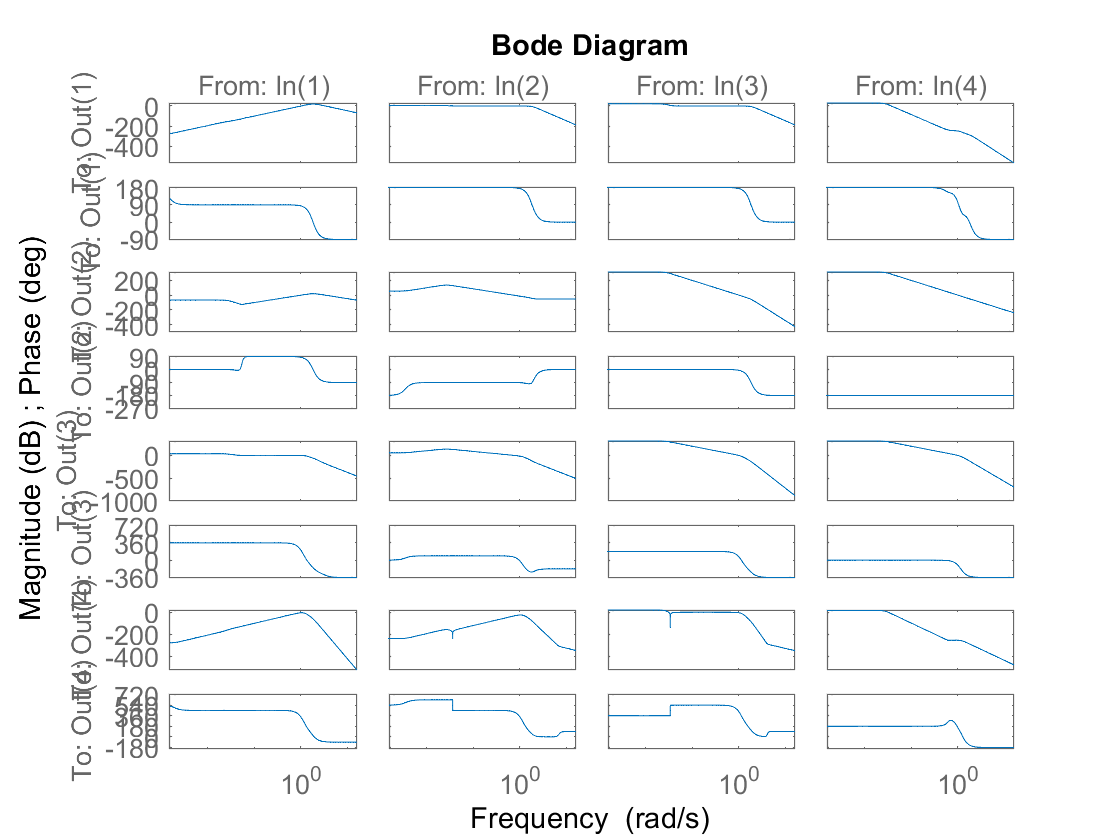


bode(Gss)